## Simple

states = {'omega_vsm' 'theta_vsm' 'v_d_t' 'v_q_t' 'i_D_vsc' 'i_Q_vsc' 'v_D_vsc' 'v_Q_vsc' 'i_D_poc' 'i_Q_poc'}

states = 1×10 cell array
    {'omega_vsm'}    {'theta_vsm'}    {'v_d_t'}    {'v_q_t'}    {'i_D_vsc'}    {'i_Q_vsc'}    {'v_D_vsc'}    {'v_Q_vsc'}    {'i_D_poc'}    {'i_Q_poc'}




% control gains
k_d_vsm, H_vsm, omega_nom=2*pi*50, k_p_q_vsm, ki_q

k_d_vsm = 70

H_vsm = 3

omega_nom = 314.1593

k_p_q_vsm = -0.0500

ki_q = 314.1593

% plant values
r_f, l_f, c_f, r_grid, x_sys

r_f = 0.0053

l_f = 0.1056

c_f = 0.0757

r_grid = 0.0632

x_sys = 0.8768

% initial conditions
v_D0_vsc = 0.6742274999, v_Q0_vsc = 0.7452800000

v_D0_vsc = 0.6742

v_Q0_vsc = 0.7453

i_D0_vsc = 0.8528229112, i_Q0_vsc = 0.3689933190

i_D0_vsc = 0.8528

i_Q0_vsc = 0.3690

v_d0_t = 0.6352618054, v_q0_t = 0.8353380994

v_d0_t = 0.6353

v_q0_t = 0.8353

theta_0_vsc = 0.8354107558;

A = zeros(length(states),length(states))

A =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


P_meas = [v_D0_vsc v_Q0_vsc i_D0_vsc i_Q0_vsc]

P_meas =     0.6742    0.7453    0.8528    0.3690


Q_meas = [v_Q0_vsc -v_D0_vsc -i_Q0_vsc i_D0_vsc]

Q_meas =     0.7453   -0.6742   -0.3690    0.8528


v_D_t = [-v_q0_t*sin(theta_0_vsc)+v_d0_t*cos(theta_0_vsc) cos(theta_0_vsc) sin(theta_0_vsc) ]

v_D_t =    -0.1933    0.6709    0.7416


v_Q_t = [-v_d0_t*cos(theta_0_vsc)-v_q0_t*sin(theta_0_vsc) -sin(theta_0_vsc) cos(theta_0_vsc) ]

v_Q_t =    -1.0456   -0.7416    0.6709


A = [-k_d_vsm/(2*H_vsm) 0 0 0 -P_meas./(2*H_vsm) 0 0;
    omega_nom zeros(1,length(states)-1);
    0 0 k_p_q_vsm*ki_q Q_meas 0 0 0;
    zeros(1,length(states));
    0 1/l_f*v_D_t -r_f/l_f omega_nom -1/l_f 0 0 0;
    0 1/l_f*v_Q_t -omega_nom -r_f/l_f  0 -1/l_f 0 0;
    0 0 0 0 -1/c_f 0 0 omega_nom 1/c_f 0;
    0 0 0 0 0 -1/c_f -omega_nom 0 0 1/c_f;
    0 0 0 0 0 0 1/x_sys 0 -r_grid/x_sys omega_nom;
    0 0 0 0 0 0 0 1/x_sys -omega_nom -r_grid/x_sys]

A =   -11.6667         0         0         0   -0.1124   -0.1242   -0.1421   -0.0615         0         0
  314.1593         0         0         0         0         0         0         0         0         0
         0         0  -15.7080    0.7453   -0.6742   -0.3690    0.8528         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0   -1.8307    6.3543    7.0240   -0.0500  314.1593   -9.4717         0         0         0
         0   -9.9040   -7.0240    6.3543 -314.1593   -0.0500         0   -9.4717         0         0
         0         0         0         0  -13.2100         0         0  314.1593   13.2100         0
         0         0         0         0         0  -13.2100 -314.1593         0         0   13.2100
         0         0         0         0         0         0    1.1405         0   -0.0721  314.1593
         0         0         0         0         0         0         0    1.1405 -314.1



inputs = {'P_ref' 'Q_ref' 'v_D_grid' 'v_Q_grid' 'theta_grid'}

inputs = 1×5 cell array
    {'P_ref'}    {'Q_ref'}    {'v_D_grid'}    {'v_Q_grid'}    {'theta_grid'}



B = [1/(2*H_vsm) 0 0 0 0;
    zeros(1,length(inputs));
    0 k_p_q_vsm 0 0 0;
    zeros(1,length(inputs));
    0 0 0 0 -1*(-v_q0_t*sin(theta_0_vsc)+v_d0_t*cos(theta_0_vsc))/l_f; % for obtaining theta_vsc
    0 0 0 0 -1*(-v_d0_t*cos(theta_0_vsc)-v_q0_t*sin(theta_0_vsc))/l_f; % for obtaining theta_vsc
    0 0 0 0 0;
    0 0 0 0 0;
    0 0 -1/c_f 0 0;
    0 0 0 -1/c_f  0]

B =     0.1667         0         0         0         0
         0         0         0         0         0
         0   -0.0500         0         0         0
         0         0         0         0         0
         0         0         0         0    1.8307
         0         0         0         0    9.9040
         0         0         0         0         0
         0         0         0         0         0
         0         0  -13.2100         0         0
         0         0         0  -13.2100         0



outputs = {'P_vsc' 'Q_vsc' 'theta_vsc'}

outputs = 1×3 cell array
    {'P_vsc'}    {'Q_vsc'}    {'theta_vsc'}



C = [0 0 0 0 P_meas 0 0;
    0 0 0 0 Q_meas 0 0;
    0 1 zeros(1,length(states)-2)];
D = [zeros(1,length(inputs));
    zeros(1,length(inputs));
    0 0 0 0 -1]

D =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0    -1



sys_mimo = ss(A,B,C,D,Ts_power,'statename',states,...
'inputname',inputs,...
'outputname',outputs);
sys_mimo

sys_mimo =
 
  A = 
              omega_vsm  theta_vsm      v_d_t      v_q_t    i_D_vsc    i_Q_vsc    v_D_vsc    v_Q_vsc    i_D_poc    i_Q_poc
   omega_vsm     -11.67          0          0          0    -0.1124    -0.1242    -0.1421    -0.0615          0          0
   theta_vsm      314.2          0          0          0          0          0          0          0          0          0
   v_d_t              0          0     -15.71     0.7453    -0.6742     -0.369     0.8528          0          0          0
   v_q_t              0          0          0          0          0          0          0          0          0          0
   i_D_vsc            0     -1.831      6.354      7.024      -0.05      314.2     -9.472          0          0          0
   i_Q_vsc            0     -9.904     -7.024      6.354     -314.2      -0.05          0     -9.472          0          0
   v_D_vsc            0          0          0          0     -13.21          0          0      314.2      13.21        

tf(sys_mimo)

ans =
 
  From input "P_ref" to output...
                            -451.1 z^6 - 9.096e04 z^5 - 8.693e07 z^4 - 1.862e10 z^3 - 4.329e12 z^2 - 9.518e14 z - 1.396e16
   P_vsc:  --------------------------------------------------------------------------------------------------------------------------------
           z^9 + 27.62 z^8 + 2.96e05 z^7 + 8.143e06 z^6 + 2.928e10 z^5 + 8.018e11 z^4 + 9.695e14 z^3 + 2.637e16 z^2 + 1.755e17 z - 1.396e16
 
                            278.2 z^6 - 1.319e05 z^5 + 5.045e07 z^4 - 2.716e10 z^3 + 2.043e12 z^2 - 1.396e15 z - 2.251e16
   Q_vsc:  --------------------------------------------------------------------------------------------------------------------------------
           z^9 + 27.62 z^8 + 2.96e05 z^7 + 8.143e06 z^6 + 2.928e10 z^5 + 8.018e11 z^4 + 9.695e14 z^3 + 2.637e16 z^2 + 1.755e17 z - 1.396e16
 
                           52.36 z^7 + 835.3 z^6 + 1.549e07 z^5 + 2.457e08 z^4 + 1.53e12 z^3 + 2.414e13 z^2 + 5.048e16 z + 7.918e17
   theta_vsc:  --

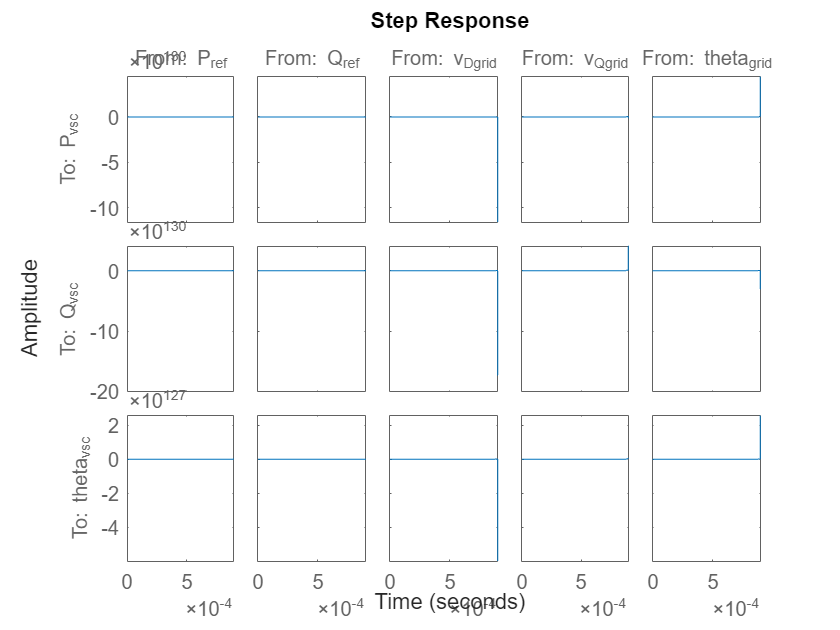

step(sys_mimo)

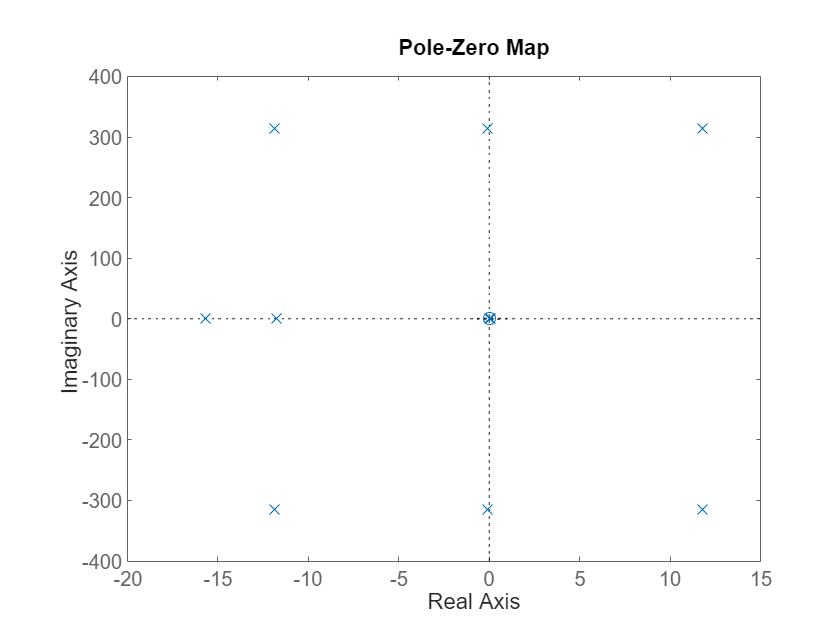

pzmap(sys_mimo)

Amat = sys_mimo.A

Amat =   -11.6667         0         0         0   -0.1124   -0.1242   -0.1421   -0.0615         0         0
  314.1593         0         0         0         0         0         0         0         0         0
         0         0  -15.7080    0.7453   -0.6742   -0.3690    0.8528         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0   -1.8307    6.3543    7.0240   -0.0500  314.1593   -9.4717         0         0         0
         0   -9.9040   -7.0240    6.3543 -314.1593   -0.0500         0   -9.4717         0         0
         0         0         0         0  -13.2100         0         0  314.1593   13.2100         0
         0         0         0         0         0  -13.2100 -314.1593         0         0   13.2100
         0         0         0         0         0         0    1.1405         0   -0.0721  314.1593
         0         0         0         0         0         0         0    1.1405 -31

e = eig(Amat)

e = 1.0e+02 *

   0.0008 + 0.0000i
  -0.1174 + 0.0000i
  -0.1568 + 0.0000i
   0.1180 + 3.1416i
   0.1180 - 3.1416i
  -0.1187 + 3.1416i
  -0.1187 - 3.1416i
  -0.0007 + 3.1416i
  -0.0007 - 3.1416i
   0.0000 + 0.0000i


% [V,D,W] = eig(Amat) 

## extended


x_states =["theta_gfm" "omega_gfm" "v_o_D" "v_o_Q" "i_l_D" "i_l_Q" "v_ref_d" "phi_d" "phi_q" "gamma_d" "gamma_q" "i_f_d" "i_f_q" "v_dc"]'

x_states = 14×1 string array
    "theta_gfm"
    "omega_gfm"
    "v_o_D"
    "v_o00_Q"
    "i_l_D"
    "i_l_D"
    "v_ref_d"
    "phi_d"
    "phi_q"
    "gamma_d"
    "gamma_q"
    "i_f_d"
    "i_f_q"
    "v_dc"


u_inputs =["P_mppt" "V_g_D" "V_g_Q" "Q_ref"]


u_inputs =

     []



a = zeros(length(x_states),length(x_states))

a =      0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0


b = zeros(length(x_states),length(u_inputs))




%theta_gfm
a(1,1) = "omega_nom";

% omega_gfm
a(2,2) = "-k_d_vsm/(2*H_vsm)";
a(2,3) = "-I_l_D0/(2*H_vsm)";
a(2,4) = "-I_l_Q0/(2*H_vsm)";
a(2,5) = "-V_o_D0/(2*H_vsm)";
a(2,6) = "-V_o_Q0/(2*H_vsm)";
b(2,1) = "1/(2*H_vsm)";

%v_o_D
a(3,1) = "-i_f_q0*sin(theta_0)+i_f_d0*cos(theta_0)"
a(3,4) = "omega_nom";
a(3,5) = "-1/c_f";
a(3,12) = "1/c_f*cos(theta_0)";
a(3,13) = "1/c_f*sin(theta_0)";
%v_o_Q
a(4,1) = "-i_f_d0*cos(theta_0)-i_f_q0*sin(theta_0)"
a(4,3) = "-omega_nom";
a(4,6) = "-1/c_f";
a(4,12) = "-1/c_f*sin(theta_0)";
a(4,13) = "1/c_f*cos(theta_0)";

%i_l_D
a(5,5) = "-r_g/l_g";
a(5,6) = "omega_nom";
a(5,2) = "1/l_g";
b(5,2) = "-1/l_g";

%i_l_Q
a(6,6) = "-r_g/l_g";
a(6,5) = "-omega_nom";
a(6,3) = "1/l_g";
b(6,3) = "-1/l_g";

%v_ref_d
a(7,7) = "-1";
a(7,3) = "-1*(-I_l_Q0*k_i_q)";
a(7,4) = "-1*(I_l_D0*k_i_q)";
a(7,5) = "-1*(V_o_Q0*k_i_q)";
a(7,6) = "-1*(-V_o_D0)*k_i_q";
b(7,4) = "k_i_q"

%phi _d
a(8,7) = "1";
a(8,3) = 



